# Taller I

### 23/03/2022 2022-01S

#### Métodos Númericos

#### Bisección y Punto Fijo

Se resuelven los ejercicios $7,9,12,14$, se propone el uso de Bisección, punto fijo y Newton

**7) **Dibuje en la misma figura las funciones $y=x$ y $y=\tan \left(x\right)$. Use el método de bisección con tolerancia 1e − 5 para aproximar el primer valor positivo de $x$ tal que $x=\tan \left(x\right)$

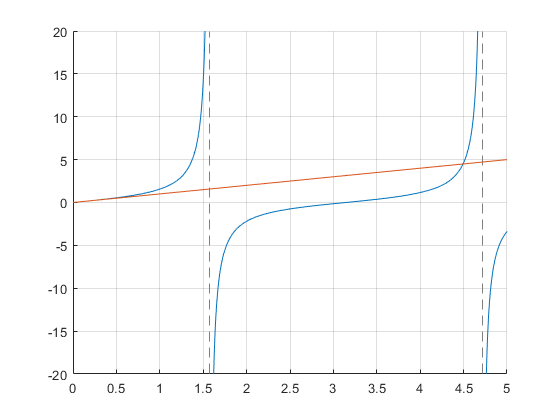

clear
syms f(x) g(x)
f(x) = tan(x); % Definamos las funciones
g(x) = x;


clf('reset') % Limpiar la figura
hold on % Juntar los gráficos en la misma figura
fplot(f, [0, 5]) % Gráfico de f
fplot(g, [0, 5]) % Gráfico de f
grid on % Activamos la gradilla
hold off % Terminamos el juntar funciones

G(x) = f(x) - g(x) % Definimos función auxiliar

$$G(x) = \tan\left(x\right)-x$$

dG(x) = diff(G, x);
[c, err, n] = bisect(G, 4.4, 4.6, 1e-5) % Resolvemos bisección

c = 4.4934

err = 2.4414e-05

n = 13

G = matlabFunction(G) % Matematica -> Matlab

G = function_handle with value:
    @(x)-x+tan(x)


dG = matlabFunction(dG);
[p0, err, k, y] = newton(G, dG, 4.5, 1e-5, 1e-5, 20) % Resolvemos Newton

p0 = 4.4934

err = 2.0425e-04

k = 2

y = 3.9797e-06

**9) **Dibuje en la misma figura las funciones $y=e^x -2$ y $y=\cos \left(e^x -2\right)$ . Use el método de bisección con tolerancia 1e − 5 para aproximar un valor $x\in \left\lbrack 0\ldotp 5,\;1\ldotp 5\right\rbrack$tal que $e^x -2=\cos \left(e^x -2\right)$

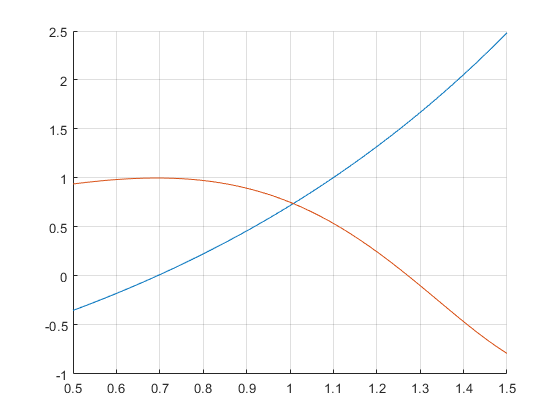

clear
syms x

f = @(x) exp(x) - 2;
g = @(x) cos(exp(x) - 2);

clf('reset')
hold on
fplot(f, [.5, 1.5])
fplot(g, [.5, 1.5])
grid on
hold off

F = @(x) f(x) - g(x); % Función auxiliar
c = bisect(F, .5, 1.5, 1e-5) % Resolvemos por bisección

c = 1.0076

diff(F, x) % Valor de la derivada

$$ans = {\mathrm{e}}^{x}+{\mathrm{e}}^{x}\,\sin\left({\mathrm{e}}^{x}-2\right)$$

dF = @(x) exp(x) + exp(x)*sin(exp(x) - 2); % Escribimos la función derivada
c = newton(F, dF, .6, 1e-5, 1e-5, 20)

c = 1.0076

**12)** Aproxime el punto fijo de la función $g\left(x\right)=\cos \left(x\right)$ en el intervalo $\left\lbrack 0,1\right\rbrack$. Utilice $p_0 =1$ como primera aproximación

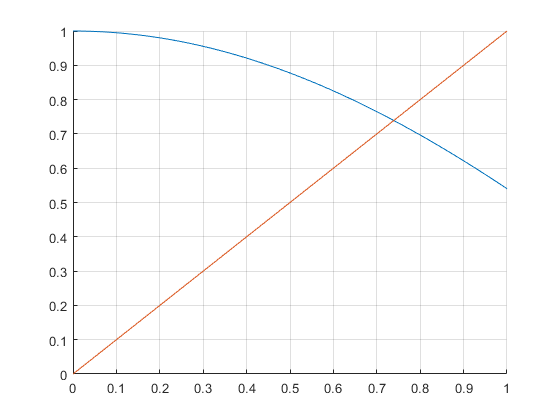

clear
syms g(x)

g(x) = cos(x);

clf('reset')
hold on
fplot(g, [0, 1])
fplot(x, [0, 1])
grid on
hold off

g = matlabFunction(g)

g = function_handle with value:
    @(x)cos(x)


[c, err, yc, n] = setpoint(g, 0, 1, 1e-5)

c = 0.7391

err = 8.2522e-06

yc = 0.7391

n = 28

**14) **Este punto lo realizaremos por aparte para poder realizar la manipulación manual de las definiciones.


$$g_1 \left(x\right)=x=\;{\left(3+x-2\;x^2 \right)}^{\frac{1}{4}}$$



$$g_2 \left(x\right)={\left(\frac{x+3}{x^2 +2}\right)}^{\frac{1}{2}}$$



$$g_3 \left(x\right)=x=\;\frac{3x^4 +2x^2 +3}{4x^3 +4\;x-1}$$



$$\frac{3x^4 +2x^2 +3}{f^{\prime } \left(x\right)}\to \frac{3x^4 +2x^2 +3+f\left(x\right)-f\left(x\right)}{f^{\prime } \left(x\right)}$$
 

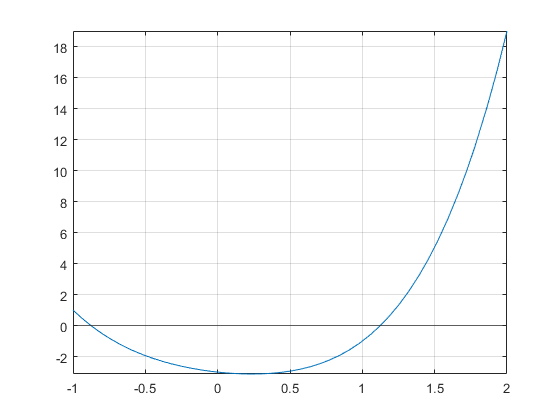

clear
syms f(x) g_1(x) g_2(x) g_3(x)

f(x) = x^4 + 2*x^2 - x - 3;
g_1(x) = (3 + x - 2*x^2)^(1 / 4);
g_2(x) = ((x + 3)/(x^2 + 2))^(1/2);
g_3(x) = (x^4 + 2*x^2 + 3) / (4*x^3 + 4*x - 1);

fplot(f, [-1, 2])
yline(0)
grid on

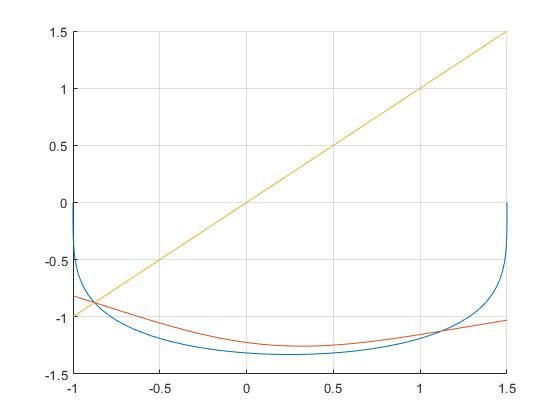

clf('reset')
hold on
fplot(-g_1, [-1, 1.5])
fplot(-g_2, [-1, 1.5])
fplot(x, [-1, 1.5])
grid on
hold off

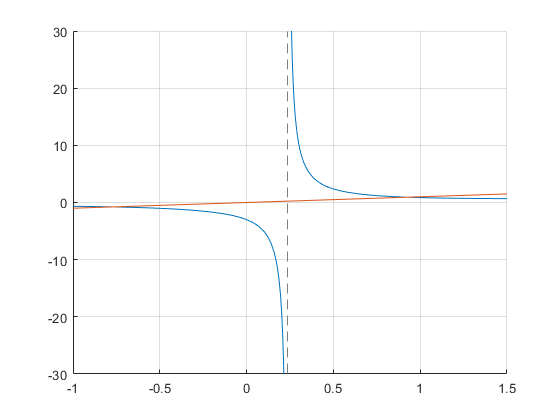

clf('reset')
hold on
fplot(g_3, [-1, 1.5])
fplot(x, [-1, 1.5])
grid on
hold off

#### Orden de convergencia & Método de Newton

Se resuelven los ejercicios $2,4\ldotp b,6$, se propone el uso de Newton

**2) **Utilice el método de Newton para aproximar el valor de x que produce el valor de $y=\frac{1}{x}$ más cercano al punto $\left(2,1\right)$.

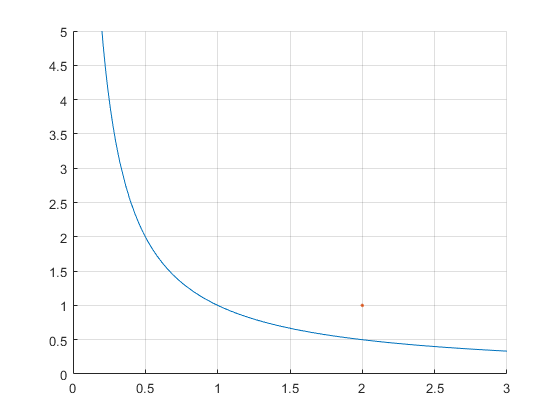

clear
syms f(x) D(x)

f(x) = 1 / x;

clf('reset')
hold on
fplot(f, [.2, 3])
plot(2, 1, '.')
hold off
grid on

D(x) = (2 - x)^2 + (1 - f(x))^2

$$D(x) = {\left(x-2\right)}^{2}+{\left(\frac{1}{x}-1\right)}^{2}$$

dD(x) = diff(D, x)

$$dD(x) = 2\,x-\frac{2\,\left(\frac{1}{x}-1\right)}{x^{2}}-4$$

c = eval(solve(dD))

c =    0.5000 - 0.6067i
   0.5000 + 0.6067i
  -0.8668 + 0.0000i
   1.8668 + 0.0000i


Teorico = c(4) % Raiz Teorica

Teorico = 1.8668

% Definición de Newton
d2D = diff(dD, x)

$$d2D(x) = \frac{4\,\left(\frac{1}{x}-1\right)}{x^{3}}+\frac{2}{x^{4}}+2$$

[c, err, k, y] = newton(dD, d2D, 2, 1e-5, 1e-5, 20)

$$c = \frac{1078112}{577531}$$

$$err = \frac{812}{8662965}$$

k = 2

$$y = -\frac{112184766568529}{361856972308210679824384}$$

eval(c)

ans = 1.8668

dD = matlabFunction(dD);
d2D = matlabFunction(d2D);

[c, err, k, y] = newton(dD, d2D, 2, 1e-5, 1e-5, 20)

c = 1.8668

err = 9.3732e-05

k = 2

y = -3.1003e-10

Teorico - c 

ans = 1.6498e-10

**4) **Para los siguientes problemas de la forma $f\left(x\right)=0$, aproxime una raíz por medio del método de Newton

**b. **$2^{-x} +e^x +2\;\cos \left(x\right)-6=0$, en $\left\lbrack 1,3\right\rbrack$

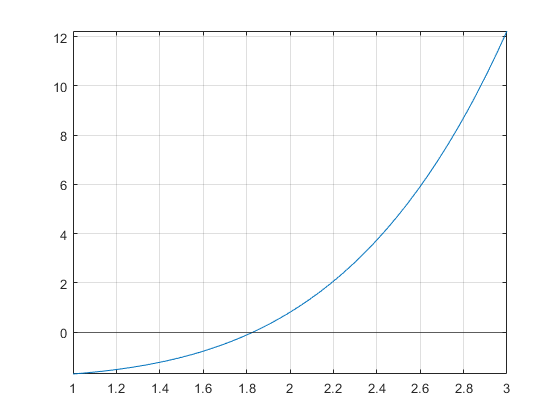

clear
syms f(x)

f(x) = 2^(-x) + exp(x) + 2*cos(x) - 6;
df(x) = diff(f, x);

clf('reset')
fplot(f, [1, 3])
yline(0)
grid on

f = matlabFunction(f);
df = matlabFunction(df);
[c, err, k, y] = newton(f, df, 3, 1e-5, 1e-5, 20)

c = 1.8294

err = 3.5046e-04

k = 5

y = 4.2242e-07

**6) **Se usa el método de Newton para aproximar la raiz 0 de


$$x\;e^x -e^x +1=0$$
 

¿Cuál es el orden de convergencia del método de Newton para este ejemplo? Justifique su respuesta

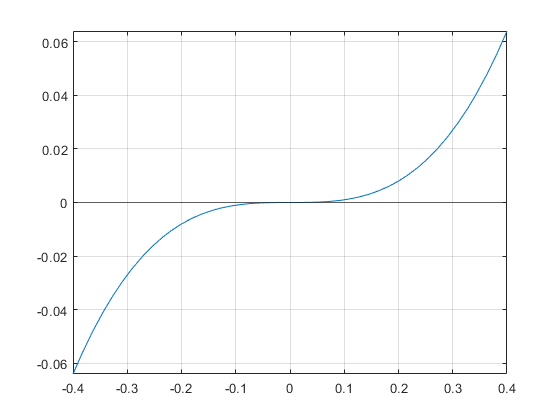

clear
syms f(x)

f(x) = x*exp(x) - exp(x) + 1;
df(x) = diff(f, x);
d2f(x) = diff(df, x);
d3f(x) = diff(d2f, x);

clf('reset')
fplot(x^3, [-.4, .4])
yline(0)
grid on

Cero de multiplicidad par.

f(0), df(0), d2f(0), d3f(0) % Multiplicidad de la raiz es 2

$$ans = 0$$

$$ans = 0$$

$$ans = 1$$

$$ans = 2$$

f = matlabFunction(f);
df = matlabFunction(df);
d2f = matlabFunction(d2f);

Newton:

[p0, err, k, y] = newton(f, df, 1/2, 1e-5, 1e-5, 20)

p0 = 0.0027

err = 0.0027

k = 8

y = 3.6585e-06

Newton Acelerado: $x_{k+1} =x_k -M\frac{f\left(x_k \right)\;}{f^{\prime } \left(x_k \right)}$

Mdf = @(x) df(x) / 2;
[p0, err, k, y] = newton(f, Mdf, 1/2, 1e-5, 1e-5, 20)

p0 = 0.0018

err = 0.0721

k = 2

y = 1.5971e-06

Newton Modificado:

[p0, diferencia, k, y] = newtonMod(f, df, d2f, 1/2, 1e-5, 1e-5, 20)

p0 = -0.0027

diferencia = 0.0878

k = 2

y = 3.6091e-06